%simulate the mouse's behavior using 761 data


%%--------------------------------------------------------------------
%get the parameters estimation first


RL_algorithm='Lee';  %Daeyeol's reinforcement model from 2004 NN

base_dir= 'E:\data\matching_pennies\761\model_A2\';

%get history data
[c_nomiss, r_nomiss, com_nomiss]=getData(base_dir);

if RL_algorithm=='Lee'
    ans=fit_modelMP(c_nomiss, r_nomiss);
    alpha_fit=ans(1); delta1_fit=ans(2); delta0_fit=ans(3);
end


Local minimum possible.

fminunc stopped because the size of the current step is less than
the selected value of the step size tolerance.

<stopping criteria details>


Computing finite-difference Hessian using objective function.


ans

ans =     0.9320    0.0079
    0.1323    0.0127
    0.0698    0.0084


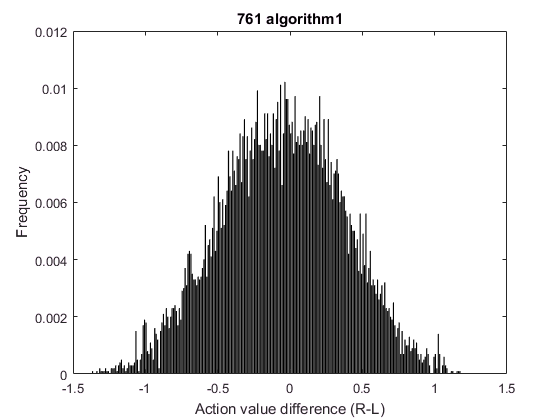

%get the action value plot 
v_difference=get_action_value(c_nomiss, r_nomiss, alpha_fit, delta1_fit, delta0_fit);

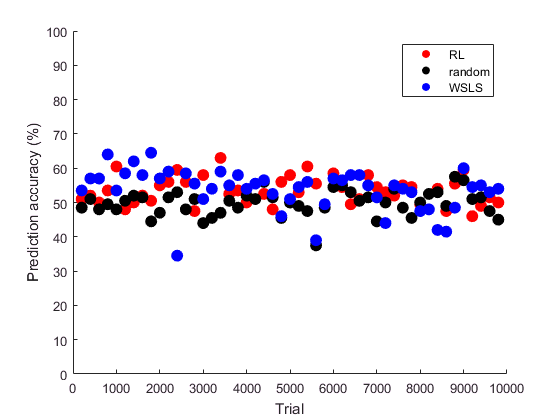

%predict the animal's choice using v_difference
[c_RL, c_random, c_WSLS]=predict_choice(c_nomiss,r_nomiss,v_difference);


xpar=[alpha_fit, delta1_fit, delta0_fit]; data=[c_nomiss double(r_nomiss)];
[AIC_RL, AIC_random, AIC_WSLS]=AIC_estimation(xpar, data);
%notice that minimal AIC indicates the best model
%where in this case, reinforcement learning model has the minimum
%AIC--great!

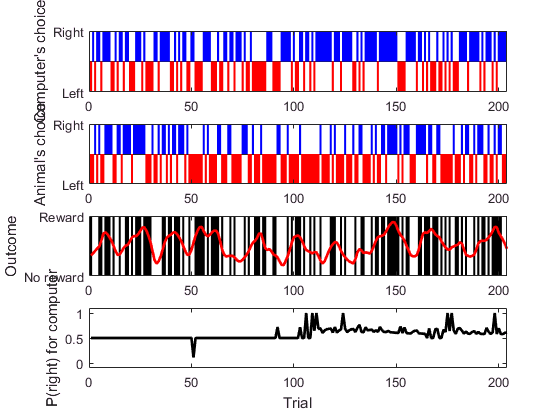


%next: find out a way to detect the parameter change %logsitic regression


%get simulated data
N=1200; %number of altered trials
alpha=alpha_fit; delta1=delta1_fit; delta0=delta0_fit;
index=1; change=1; %change alpha to 80% first
[c_simu, r_simu, com_simu, comprob_simu,altered_tList]=simu_modelMP(N, alpha, delta1, delta0,index, change);

%plot a example session (first);
 plot_first_session(c_simu(1:204), r_simu(1:204), com_simu(1:204), comprob_simu(1:204));

%looks fine, now doing the model_fitting %try original Daeyeol model then
%q-learning

%refit the model
c_fit=(c_simu-2.5).*2; %change 2/3 to -1/1 to suit the function

%newans=fit_altered_modelMP(c_fit,r_simu,altered_tList, init)

Index exceeds matrix dimensions.

Error in model_altered_MP (line 21)
delta1_altered=xpar(4); %only alpha_altered for now

Error in fit_altered_modelMP>@(x)model_altered_MP(x,[c,r],trials) (line 46)
[xval,fval,flag,out,grad,hess] = fminunc( @(x)model_altered_MP(x, [c r], trials), initpar, opt);

Error in 

ans=fit_modelMP(c_fit(1:8000), r_simu(1:8000))
